coords = planetCoordinates(30*24*3600);

 v_optimal = fminsearch(@(v) distanceToMars(v, coords), [30 0])
constants;
options = odeset('Events', @marsTrajectoryCrossed);
[t, u] = ode45(@rocketTrajectory, [0 366*24], [coords(1) coords(2) v_optimal])

t = 1.0e+03 *

         0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


u = 1.0e+13 *

    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000
    0.0000    0.0000   -0.0000    0.0000



rockete = u(end, 1:2)

rockete = 1.0e+13 *

    1.1235    0.5571


coords = planetCoordinates(t(end))

coords = 1.0e+08 *

    1.4960
    0.0026
    2.2790
    0.0021


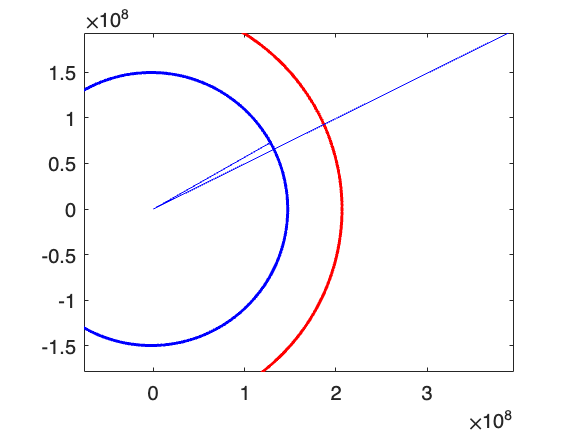


theta = linspace(0, 2*pi, 1000);
[x_e, y_e, x_m, y_m, x_s, y_s] = calculatePlanetPositions(theta);
figure;    
plot(x_e, y_e, 'b', 'LineWidth', 1.5);
hold on;
plot(x_m, y_m, 'r', 'LineWidth', 1.5);
plot(u(:, 1), u(:, 2), 'b-');
axis equal;

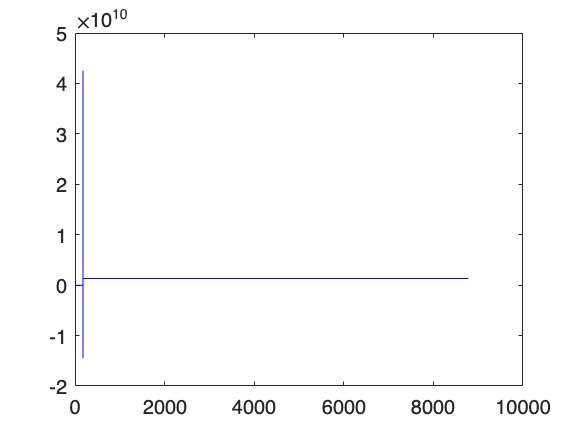

figure;
plot(t, u(:, 3), 'b-');